Highly-simplified program for simulating the epidemic in New York City from 12/29/2020 to 3/31/2021.

- S = Susceptible

- I = Infected

- R = Recovered

- L = Lost

- LPD = Lost Per Day

All times measured in days.

clear;

dt = 1e-3; % timestep
tMax = 92; % simulation time
t = 0:dt:tMax; % time vector

% array preallocation
S = zeros(1,tMax/dt);
I = zeros(1,tMax/dt);
R = zeros(1,tMax/dt);
dSodt = zeros(1,tMax/dt);
dRodt = zeros(1,tMax/dt);
dIodt = zeros(1,tMax/dt);
LPD = zeros(1,tMax/dt);
diff = zeros(1,tMax);

r = 3e-8; % transmission rate
a = 6.66e-2; % recovery rate
b = 4.17e-3*a; % mortality rate

S(1) = 3.05e6; % initial susceptible population
I(1) = 1.72e5; % initial infected population
R(1) = 5.58e6; % initial recovered population
for i = 1:tMax/dt
    dSodt(i+1) = -r*S(i)*I(i);
    S(i+1) = S(i)+dSodt(i+1)*dt;
    
    dRodt(i+1) = a*I(i);
    R(i+1) = R(i)+dRodt(i+1)*dt;
    
    dIodt(i+1) = -dSodt(i+1)-dRodt(i+1)-b*I(i);
    I(i+1) = I(i)+dIodt(i+1)*dt;
end

L = S(1)+I(1)+R(1)-S-I-R;

LPD(1) = L(1);
for i = 1:tMax/dt
    LPD(i+1) = (L(i+1)-L(i))/dt;
end

actualT = 0:tMax;
actualLPD = [44,45,45,45,47,47,49,52,54,56,59,62,64,63,65,65,68,68,68,68,70,71,73,72,75,77,79,78,77,79,83,83,83,83,83,83,81,81,81,80,81,84,82,83,83,83,84,84,84,86,87,81,77,75,72,70,69,69,72,75,74,76,74,71,70,67,64,63,62,63,65,63,63,65,67,64,61,60,57,57,53,51,52,54,52,52,53,56,57,58,57,56,59];

for i = 1:tMax
    diff(i) = mean(LPD((i-1)/dt+2:i/dt+1))-actualLPD(i+1);
end

meanDiff = mean(diff)

meanDiff = 0.0360

RMS = sqrt(mean(diff.^2))

RMS = 4.0838

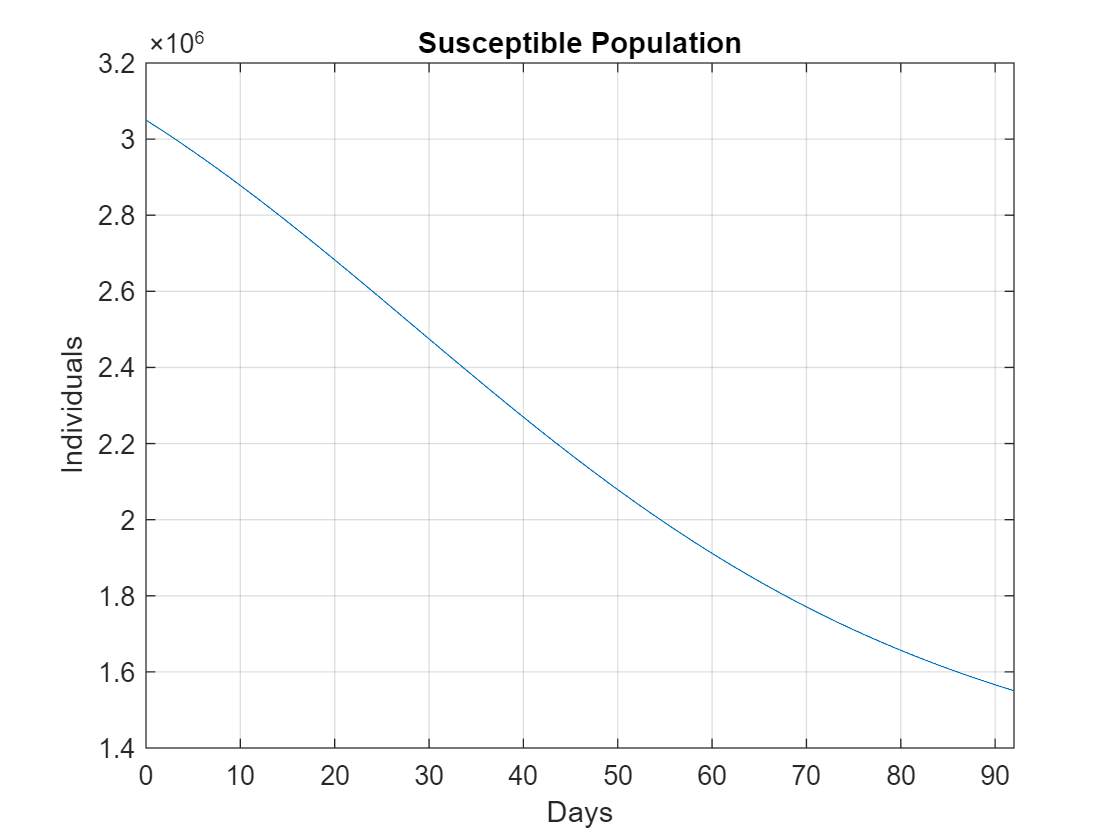


plot(t,S);
title('Susceptible Population');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

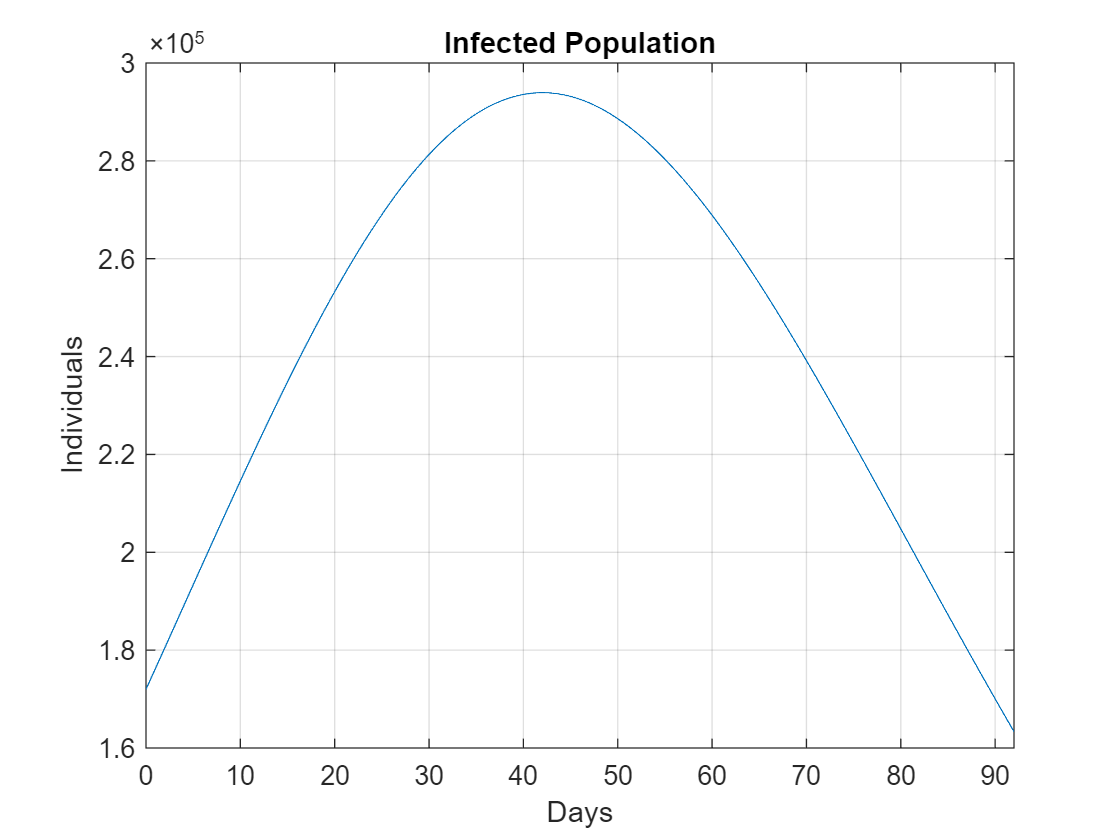

plot(t,I);
title('Infected Population');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

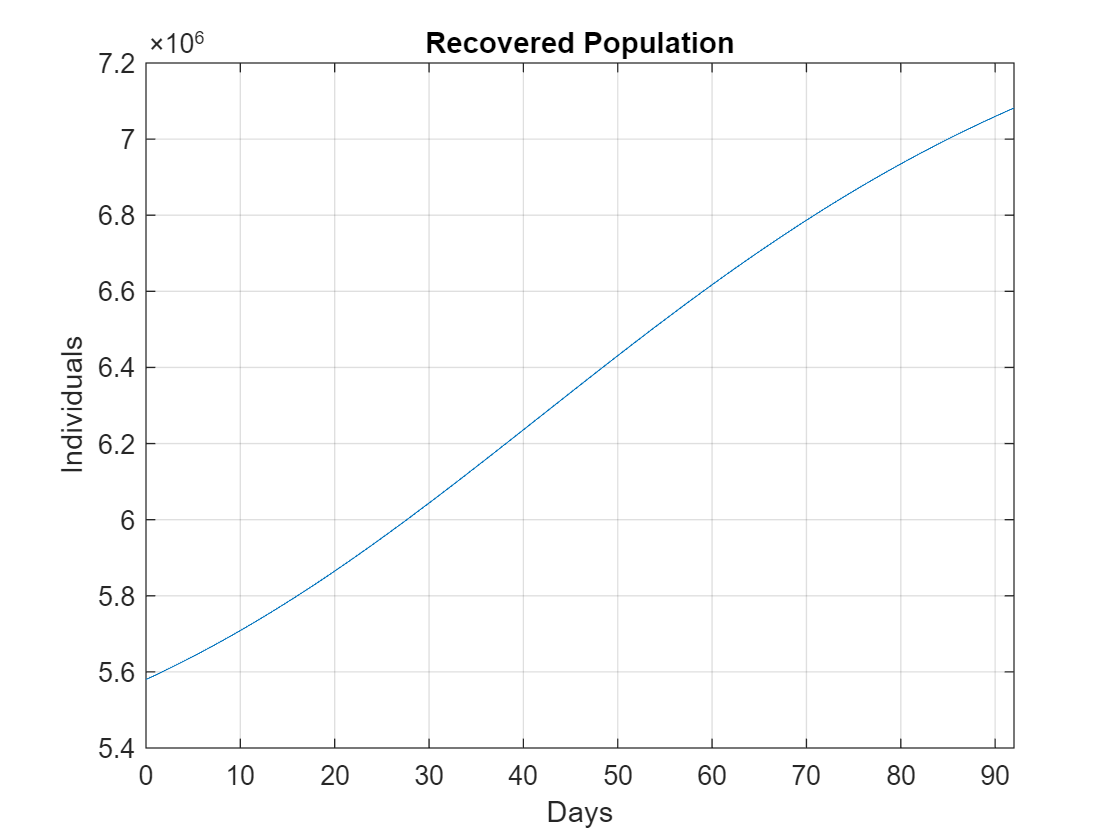

plot(t,R);
title('Recovered Population');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

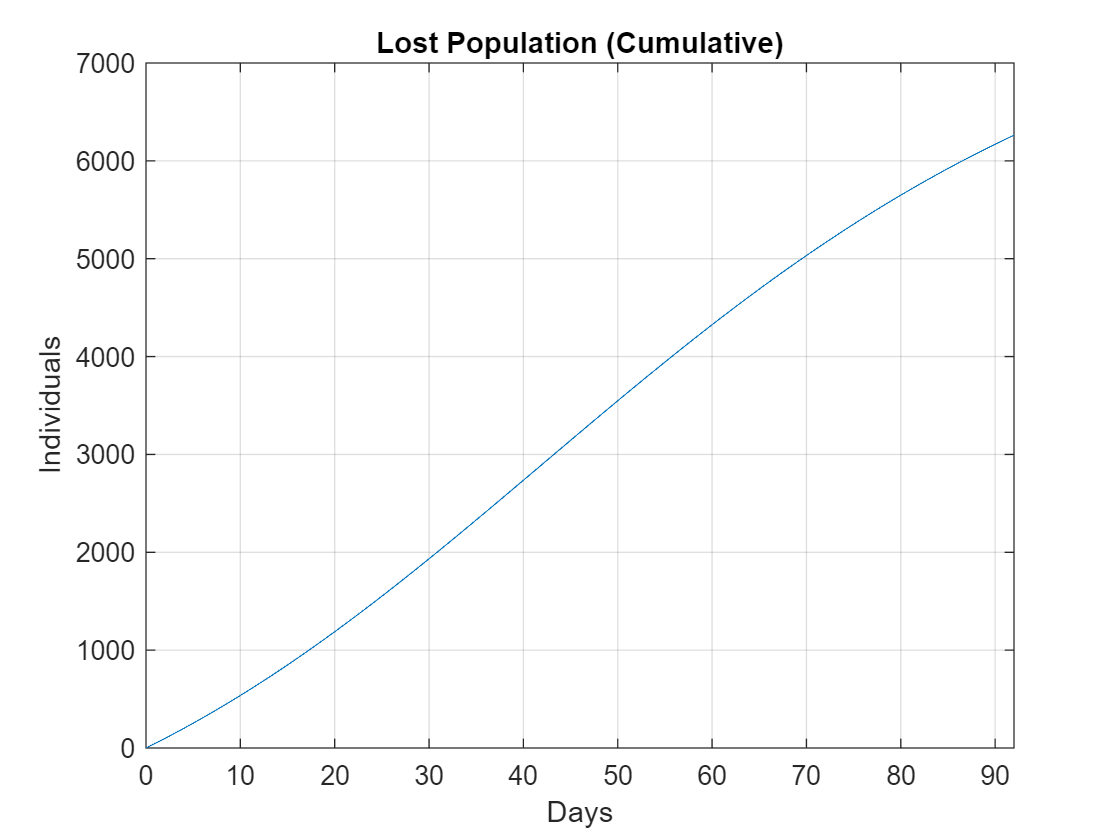

plot(t,L);
title('Lost Population (Cumulative)');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

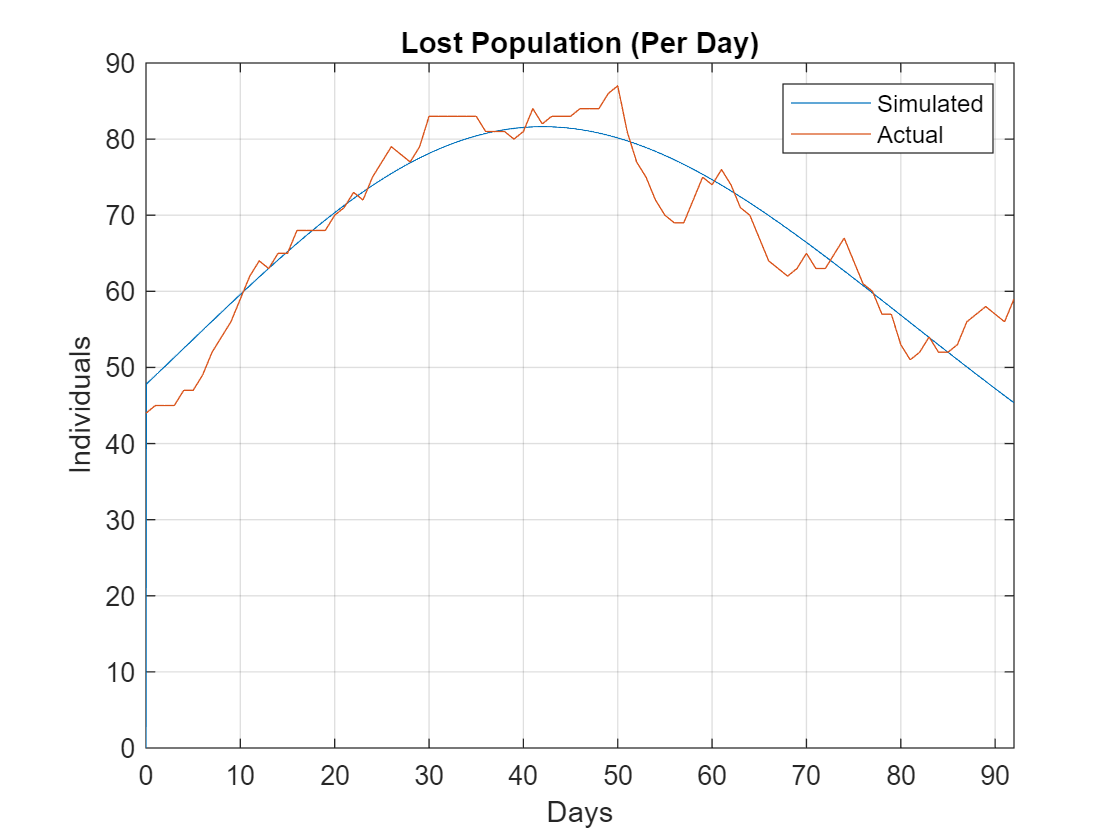

plot(t,LPD);
hold on;
plot(actualT,actualLPD);
hold off;
legend('Simulated','Actual');
title('Lost Population (Per Day)');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;